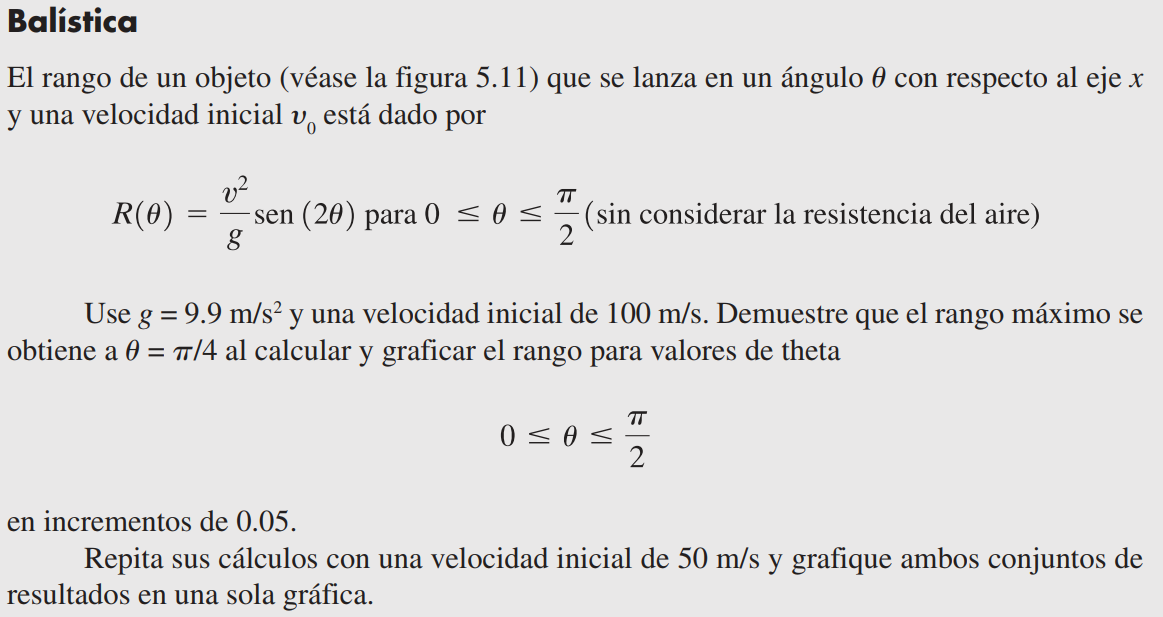

% Se define lo que se conoce.
clear
format bank

g = 9.9;
angtoRmax = pi/4;
v0 = [50 100];
ang = 0:.05:pi/2;

% Se define la relación entre v^2 y sen(2*ang).
[a, b] = meshgrid(v0.^2,sin(2*ang));

% Se encuentra R para cada ángulo y cada velocidad inicial.
R = 1/g*a.*b

R =          0         0
   25.2105  100.8418
   50.1690  200.6761
   74.6263  298.5053
   98.3380  393.3519
  121.0671  484.2682
  142.5865  570.3459
  162.6812  650.7249
  181.1505  724.6021
  197.8098  791.2393


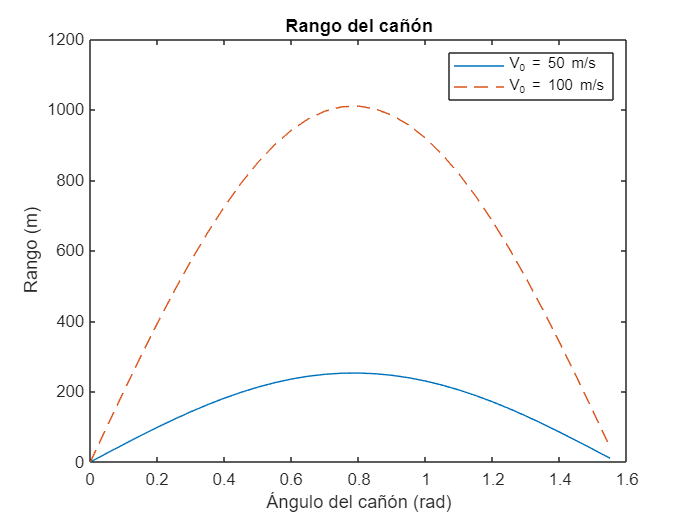

% Graficación
plot(ang,R(:,1),ang,R(:,2),'--')
title 'Rango del cañón'
xlabel 'Ángulo del cañón (rad)'
ylabel 'Rango (m)'
legend('V_{0} = 50 m/s', 'V_{0} = 100 m/s')